# Dynamic Visualization Tutorial

Copyright © 2025, The MathWorks, Inc.

## Introduction

In this tutorial, we will explore using MATLAB Handle Graphics to enhance the output of simulations in Simscape Electrical. There are three main visualization components we consider - time-series data, switches and rotating vectors. Tutorial 01 covered time-series data and switches. In this tutorial we will expand our consideration of time-series data and also cover rotating vectors.

## Three-Phase System

Open the following model that contains a balanced three-phase system feeding a resistive load, with a nominal frequency of 60Hz. Save the simulated data in new variables for ease of use. 

open_system('three_phase_01')
out = sim('three_phase_01');

time  = squeeze(out.theta.Time);
theta = squeeze(out.theta.Data);
Vabc = squeeze(out.Vabc.Data)';
Van = Vabc(:,1);
Vbn = Vabc(:,2);
Vcn = Vabc(:,3);

View the voltages and currents in the Simulation Data Inspector (SDI). 

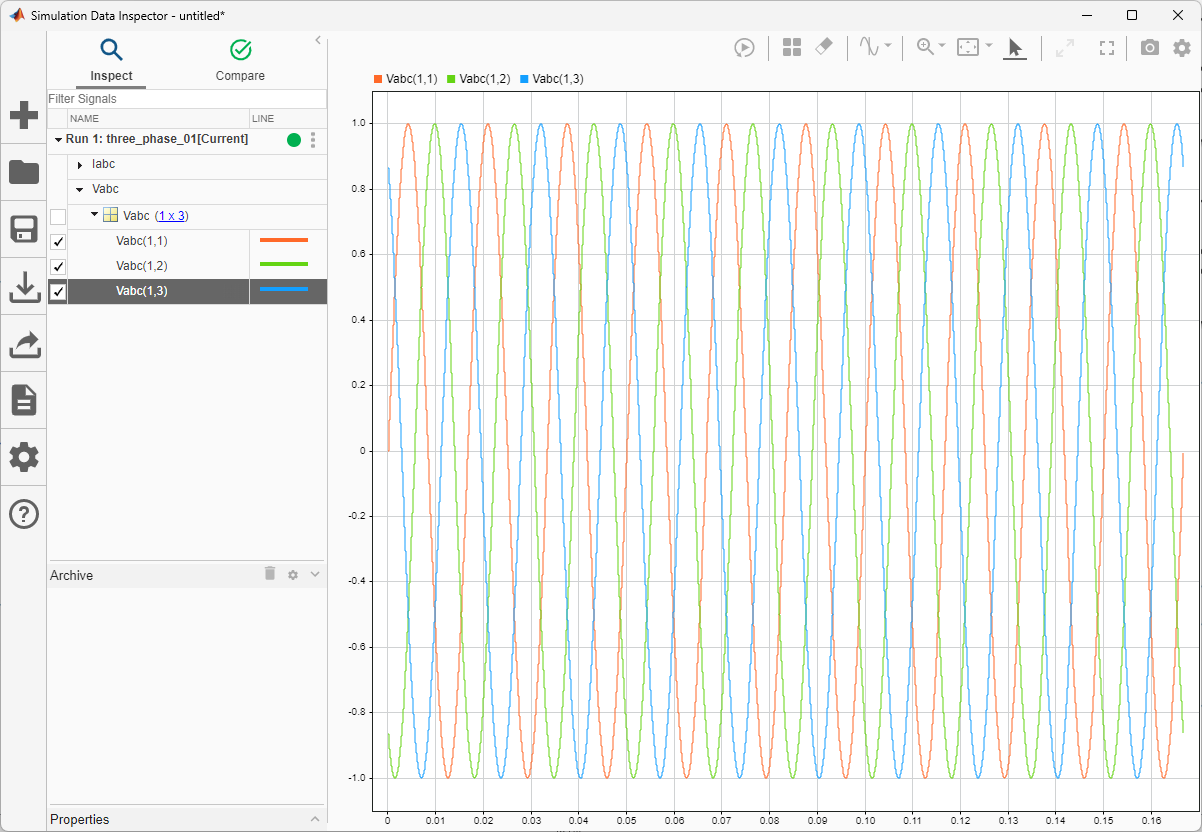

We'll now use MATLAB Handle Graphics to build a visualization of three-phase voltage.

Start by creating a figure window, and include the figure handle. Then add axes using gca (get current axes), and include the handle to the axes.

close all % close existing figures

hf = figure(1)

hf =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [583 398 560 337.4462]
       Units: 'pixels'

  Show all properties


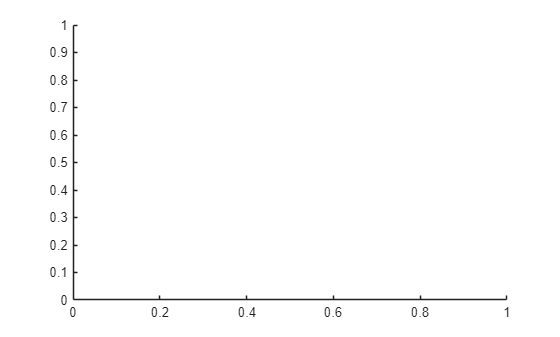

ha =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ha = gca

On the right you can see some of the properties of both hf and ha

The figure and the axes are objects and hf and ha allows us to access and modify the object properties. For example, to change the color of the figure to all white, we can use dot notation or the set command.

hf.Color = 'w';

or

set(hf,'Color','w')

OK. Let's start building a visualization of a vector. We will use the annotation command to create an arrow that will represent the phase A voltage vector.

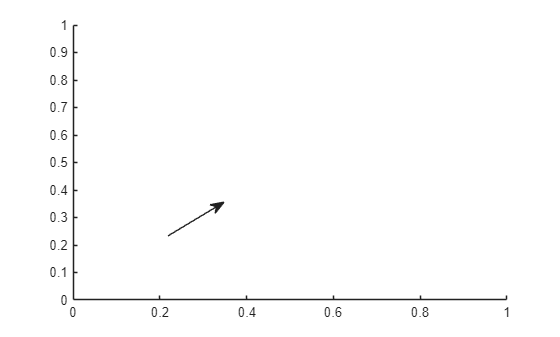

hva = annotation('arrow');

We can access some properties of hva to see the default values. We will look at the X and Y co-ordinates and also the parent of hva. Note that the parent default is 'AnnotationPane' which is the figure hf. 

xDefault = hva.X

xDefault =     0.3000    0.4000


yDefault = hva.Y

yDefault =     0.3000    0.4000


parentDefault = hva.Parent

parentDefault =     AnnotationPane


We'll spend a little more time talking about the parent and what it means for the behavior of the object. First we'll expand the axes

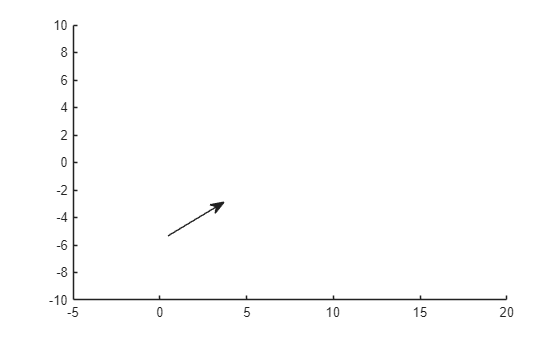

axis([-5 20 -10 10])

Notice that the arrow hasn't moved, even though we have expanded the axes. This is because the parent is the figure, and the arrow coordinates are normalized against the figure dimensions, not the axes. 

Our preference is to have the arrow coordinates referenced to the axes that we are working with. To do this, we change the parent of hva to the axes object ha, and we'll change the coordinates to have the arrow pointing straight up.

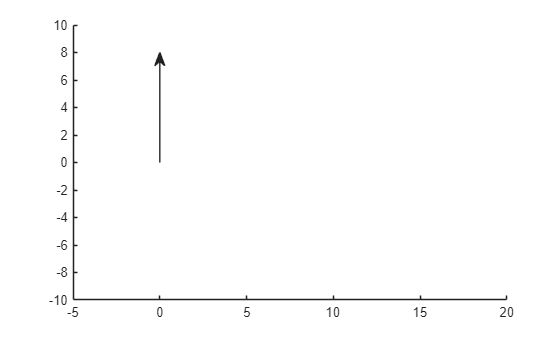

hva.Parent = ha;
hva.X = [0 0];
hva.Y = [0 8];

Things are looking good. We'll adjust some sizing and orientation so we can begin building out our full visualization

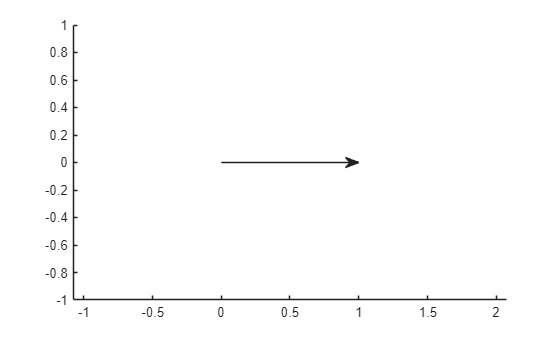

hva.X = [0 1];
hva.Y = [0 0];
axis([-1 1 -1 1],'equal')

Now we'll add a circle that the vectors will rotate in. Note that we use the  'hold on' command, as we will be working with a number of graphical elements

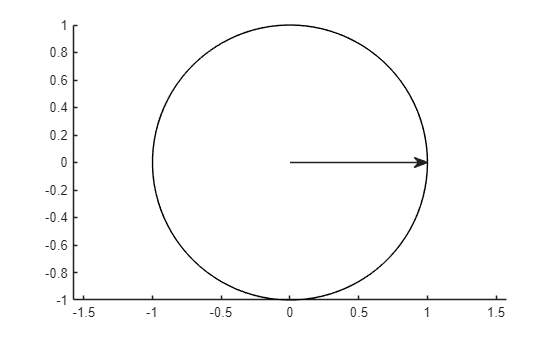

hold on
thc = linspace(0,2*pi,100); % angle for circle
plot(cos(thc),sin(thc),'k')

Now change the properties of hva. We'll make it thicker, color it red, and change the arrow head.

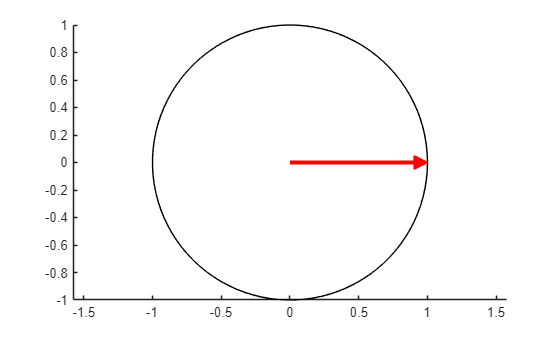

set(hva,'LineWidth',3,'Color','r','HeadStyle','plain')

Now test the rotation of van. Time step is 50 microseconds, and so two periods at 60Hz has approx. 667 time-steps.

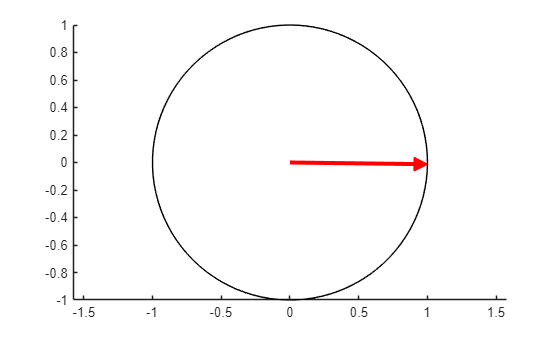

time_window = 667;

for x = 1:time_window

    set(hva,'X',[0 cos(theta(x))],'Y',[0 sin(theta(x))])

    pause(0.01)

end

Next we'll add B anc C vectors

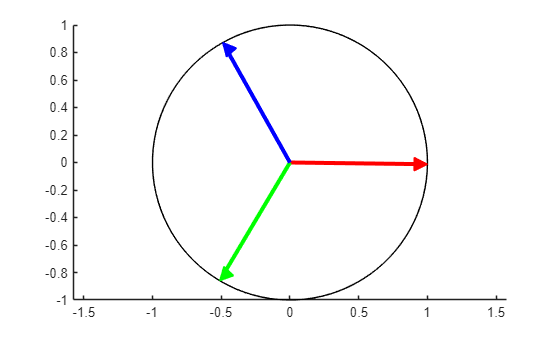

hvb = annotation('arrow','Color','g','HeadStyle','plain','LineWidth',3);
hvb.Parent = ha;
hvb.X = [0 cos(theta(x)-2*pi/3)];
hvb.Y = [0 sin(theta(x)-2*pi/3)];

hvc = annotation('arrow','Color','b','HeadStyle','plain','LineWidth',3);
hvc.Parent = ha;
hvc.X = [0 cos(theta(x)+2*pi/3)];
hvc.Y = [0 sin(theta(x)+2*pi/3)];

We'll now add a time-series plot to the left of the vectors. Set up the x-axis location of the time-series window, and decide how many time-steps you need in the x-axis. For example, we will set up the x-axis to be between x = -4.5 and x = -1.5, with 667 sample times (two periods).

xaxis = linspace(-4.5,-1.5,time_window);

Now plot Van on this axis and adjust the axis settings

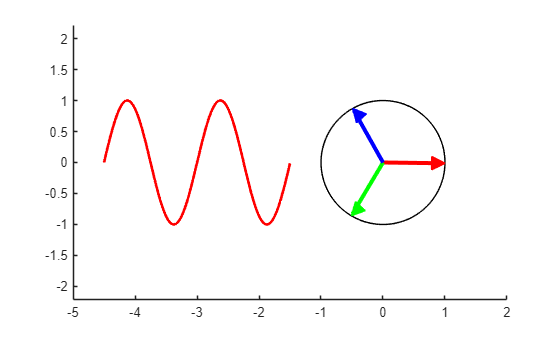

hvat = plot(xaxis,Van(1:time_window),'r','LineWidth',2);
axis([-5 2 -1.5 1.5],'equal')

Add phase B and C time-series and add a line for the x-axis

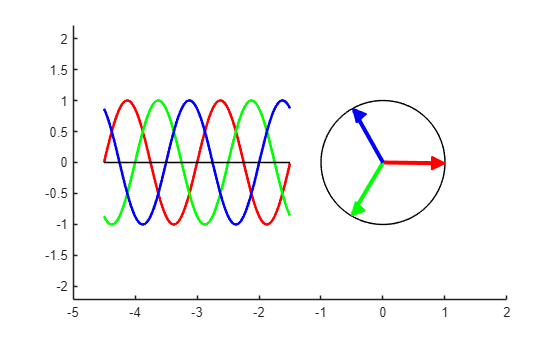

hvbt = plot(xaxis,Vbn(1:time_window),'g','LineWidth',2);
hvct = plot(xaxis,Vcn(1:time_window),'b','LineWidth',2);
plot([-4.5 -1.5],[0 0],'k')

Next add dashed lines between the arrow heads of the vectors and the time-series data. This is useful for clarifying that the vectors and time-series are matching at a given time instant

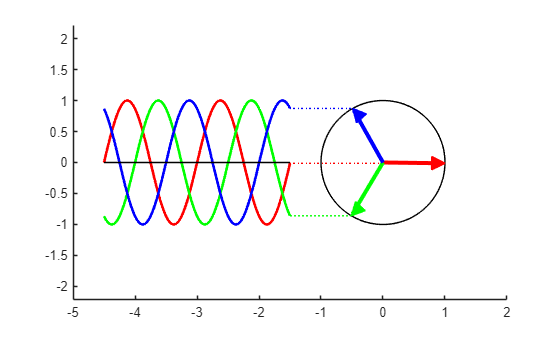

hvacl = plot([xaxis(end) hva.X(2)],[hva.Y(2) hva.Y(2)],'r:');
hvbcl = plot([xaxis(end) hvb.X(2)],[hvb.Y(2) hvb.Y(2)],'g:');
hvccl = plot([xaxis(end) hvc.X(2)],[hvc.Y(2) hvc.Y(2)],'b:');

OK. We're ready to spin the system.

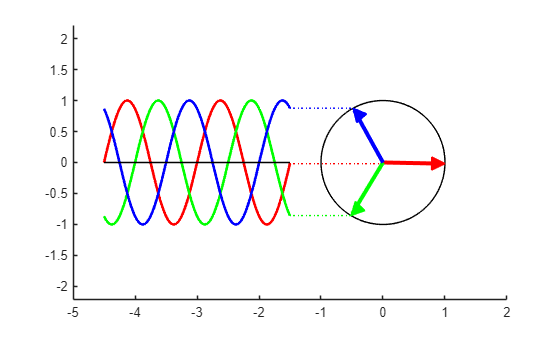

nt = numel(time);

for x = 1:nt-time_window

    hva.X = [0 cos(theta(x))];
    hva.Y = [0 sin(theta(x))];
    
    hvb.X = [0 cos(theta(x)-2*pi/3)];
    hvb.Y = [0 sin(theta(x)-2*pi/3)];
    
    hvc.X = [0 cos(theta(x)+2*pi/3)];
    hvc.Y = [0 sin(theta(x)+2*pi/3)];

    hvacl.XData = [xaxis(end) hva.X(2)];
    hvacl.YData = [hva.Y(2) hva.Y(2)];
    
    hvbcl.XData = [xaxis(end) hvb.X(2)];
    hvbcl.YData = [hvb.Y(2) hvb.Y(2)];
    
    hvccl.XData = [xaxis(end) hvc.X(2)];
    hvccl.YData = [hvc.Y(2) hvc.Y(2)];
    
    hvat.YData = Van((1:time_window)+x);
    hvbt.YData = Vbn((1:time_window)+x);
    hvct.YData = Vcn((1:time_window)+x);

    pause(0.01)

end

It would be a nice touch to add the phase sequence to the vectors as text that rotates with the vectors, so let's do that.

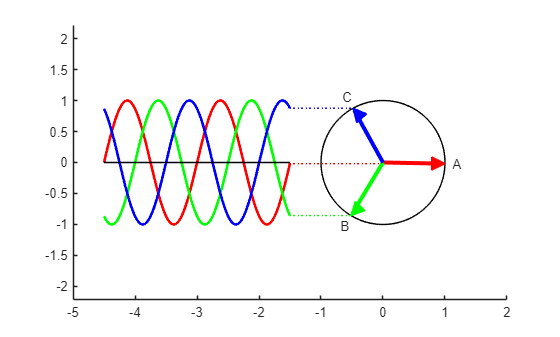

hat = text(1.2*cos(theta(1)),1.2*sin(theta(1)),'A','HorizontalAlignment','center');
hbt = text(1.2*cos(theta(1)-2*pi/3),1.2*sin(theta(1)-2*pi/3),'B','HorizontalAlignment','center');
hct = text(1.2*cos(theta(1)+2*pi/3),1.2*sin(theta(1)+2*pi/3),'C','HorizontalAlignment','center');

for x = 1:nt-667

    hva.X = [0 cos(theta(x))];
    hva.Y = [0 sin(theta(x))];
    
    hvb.X = [0 cos(theta(x)-2*pi/3)];
    hvb.Y = [0 sin(theta(x)-2*pi/3)];
    
    hvc.X = [0 cos(theta(x)+2*pi/3)];
    hvc.Y = [0 sin(theta(x)+2*pi/3)];

    hvacl.XData = [xaxis(end) hva.X(2)];
    hvacl.YData = [hva.Y(2) hva.Y(2)];
    
    hvbcl.XData = [xaxis(end) hvb.X(2)];
    hvbcl.YData = [hvb.Y(2) hvb.Y(2)];
    
    hvccl.XData = [xaxis(end) hvc.X(2)];
    hvccl.YData = [hvc.Y(2) hvc.Y(2)];
    
    hvat.YData = Van((1:time_window)+x);
    hvbt.YData = Vbn((1:time_window)+x);
    hvct.YData = Vcn((1:time_window)+x);
    
    hat.Position = 1.2*[cos(theta(x)) sin(theta(x)) 0];
    hbt.Position = 1.2*[cos(theta(x)-2*pi/3) sin(theta(x)-2*pi/3) 0];
    hct.Position = 1.2*[cos(theta(x)+2*pi/3) sin(theta(x)+2*pi/3) 0];
    
    pause(0.01)

end

END OF TUTORIAL 02